p = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
h = rand([3 1]);
h = h/norm(h);
theta = rand*2*pi-pi

theta = 0.9283


d = h'*rot(k,theta)*p;

subproblem4(h,p,k,d)

ans =    -1.2100
    0.9283


[ta,tb] = subproblem4_grt_opt(h,p,k,d)

ta = -1.2100

tb = 0.9283

[ta,tb] = subproblem4_linear(h,p,k,d)

ta = 0.9283

tb = -1.2100

N_trials = 1000

N_trials = 1000

N_attempts = 100

N_attempts = 100

T_orig = NaN([N_trials,1]);
T_linear = NaN([N_trials,1]);
T_grt_opt = NaN([N_trials,1]);

for i = 1:N_trials
    p = rand([3 1])*10;
    k = rand([3 1]);
    k = k/norm(k);
    h = rand([3 1]);
    h = h/norm(h);
    theta = rand*2*pi-pi;
    
    d = h'*rot(k,theta)*p;
%     tic;
%     for j = 1:N_attempts
%     t = subproblem4(h,p,k,d);
%     end
%     t = toc;
%     T_orig(i) = t/N_attempts;

    tic
    for j = 1:N_attempts
    [ta,tb] = subproblem4_linear(h,p,k,d);
    end
    t = toc;
    T_linear(i) = t/N_attempts;

    
    tic
    for j = 1:N_attempts
    [ta,tb] = subproblem4_grt_opt(h,p,k,d);
    end
    t = toc;
    T_grt_opt(i) = t/N_attempts;
end

T_linear = rmoutliers(T_linear);
T_orig = rmoutliers(T_orig);
T_grt_opt = rmoutliers(T_grt_opt);

mean(T_orig)

ans = NaN

mean(T_linear)

ans = 2.4533e-06

mean(T_grt_opt)

ans = 5.2634e-07


mean(T_grt_opt)/mean(T_linear)

ans = 0.2145

mean(T_linear)/mean(T_grt_opt)

ans = 4.6610

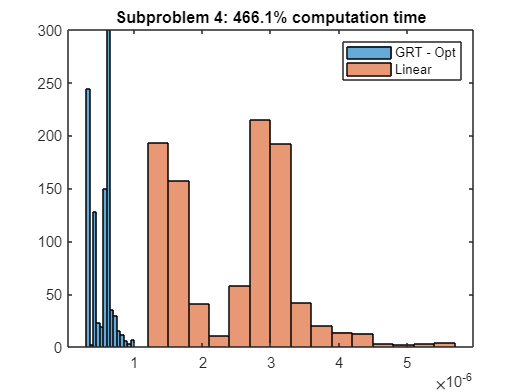


histogram(T_grt_opt); hold on
histogram(T_linear); hold off
legend("GRT - Opt", "Linear")

title("Subproblem 4: "+ num2str(mean(T_linear)/mean(T_grt_opt)*100,4) + "% computation time")


histogram(T_orig); hold on
histogram(T_grt_opt); hold off
legend("Original", "GRT - Opt")

mean(T_grt_opt)/mean(T_orig)

ans = 0.0955

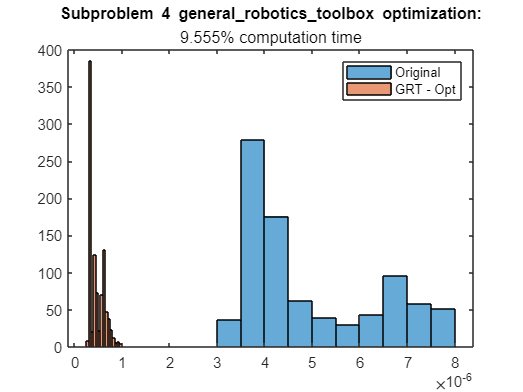

title("Subproblem 4 general\_robotics\_toolbox optimization:", num2str((mean(T_grt_opt)/mean(T_orig))*100,4) + "% computation time")

mean(T_orig)/mean(T_linear)
mean(T_linear)/mean(T_orig)

histogram(T_orig); hold on
histogram(T_linear); hold off
legend("Original", "Linear")

title("Subproblem 4: "+ num2str(mean(T_linear)/mean(T_orig)*100,4) + "% computation time")

ans = 0.2090

ans = 4.7845